# Expectations

## Notes

Expectations play a central role in financial economics. For some functions and some random variables, expectations are available in closed forms. However, for most random variables, expectations are not analytically available and so numerical solutions are needed

## Setup

Clear and reset the workspace and load required data

% Clean up everything
clear all
close all
clc
% Reset rng to make runs the same
rng('default')

## Compute expected values, variances and kurtoses

Monte carlo uses law of large numbers and i.i.d. shocks to estimate expected values. These examples show that the Monte Carlo values are close to the true value.

% Set number of samples
B = 1000;
% Standard Normal
x = randn(B,1);
ex = mean(x);
ex2 = mean(x.^2);
vx = ex2 - ex.^2;
ex4c = mean((x-ex).^4);
kx = ex4c./vx^2;
disp('Expected Values')

Expected Values


disp([0 1 1 3])

     0     1     1     3



disp('Monte Carlo Values')

Monte Carlo Values


disp([ex ex2 vx kx])

   -0.0326    0.9980    0.9969    3.2811




% Normal with mean 8% and volatility 20%
x = 0.08 + 0.2 * randn(B,1);
ex = mean(x);
ex2 = mean(x.^2);
vx = ex2 - ex.^2;
ex4c = mean((x-ex).^4);
kx = ex4c./vx^2;
disp('Expected Values')

Expected Values


disp([0.08 .2^2+0.08^2 0.2^2 3])

    0.0800    0.0464    0.0400    3.0000



disp('Monte Carlo Values')

Monte Carlo Values


disp([ex ex2 vx kx])

    0.0874    0.0475    0.0398    3.2058




% Students t
v = 8;
x = trnd(v,B,1);
ex = mean(x);
ex2 = mean(x.^2);
vx = ex2 - ex.^2;
ex4c = mean((x-ex).^4);
kx = ex4c./vx^2;
disp('Expected Values')

Expected Values


disp([0 v/(v-2) v/(v-2) (3*v-6)/(v-4)])

         0    1.3333    1.3333    4.5000



disp('Monte Carlo Values')

Monte Carlo Values


disp([ex ex2 vx kx])

    0.0404    1.3030    1.3014    4.1657




% Chi2
v = 5;
x = chi2rnd(v,B,1);
ex = mean(x);
ex2 = mean(x.^2);
vx = ex2 - ex.^2;
ex4c = mean((x-ex).^4);
kx = ex4c./vx^2;
disp('Expected Values')

Expected Values


disp([v v^2 + 2*v 2*v 3 + 12/v])

    5.0000   35.0000   10.0000    5.4000



disp('Monte Carlo Values')

Monte Carlo Values


disp([ex ex2 vx kx])

    4.9382   34.3052    9.9197    6.3581



## Log-normal

The expectation of functions other than moments can also be computed using Monte Carlo integration. This example uses the exp of a normal which is, of course, a log-normal.

mu = 0.08;
sigma2 = .2^2;
x = mu + sqrt(sigma2) * randn(B,1);
y = exp(x);

disp('Expected Values')

Expected Values


disp(exp(mu+sigma2/2))

    1.1052



disp('Monte Carlo Values')

Monte Carlo Values


disp(mean(y))

    1.1052



## Effect of additional replications

This example studies the effect of additional draws when using Monte Carlo integration. The second set uses 4 times as many, which produces estimates with a standard deviation 1/2 that of the smaller Monte Carlo (why?)

disp('Expected Values')

Expected Values


disp([v v^2 + 2*v 2*v 3 + 12/v])

    5.0000   35.0000   10.0000    5.4000




mc_values = zeros(10000,4);
for i=1:10000
    v = 5;
    x = chi2rnd(v,B,1);
    ex = mean(x);
    ex2 = mean(x.^2);
    vx = ex2 - ex.^2;
    ex4c = mean((x-ex).^4);
    kx = ex4c./vx^2;
    mc_values(i,:) = ([ex ex2 vx kx]);
end
disp('Std Deviation')

Std Deviation


disp(std(mc_values))

    0.0988    1.4736    0.6559    1.0633




mc_values4 = zeros(10000,4);
B4 = B * 4;
for i=1:10000
    v = 5;
    x = chi2rnd(v,B4,1);
    ex = mean(x);
    ex2 = mean(x.^2);
    vx = ex2 - ex.^2;
    ex4c = mean((x-ex).^4);
    kx = ex4c./vx^2;
    mc_values4(i,:) = ([ex ex2 vx kx]);
end
disp('Std Deviation (4x)')

Std Deviation (4x)


disp(std(mc_values4))

    0.0506    0.7551    0.3332    0.5386



disp('Ratio')

Ratio


disp(std(mc_values)./std(mc_values4))

    1.9514    1.9515    1.9686    1.9742



## Quadrature

Quadrature directly attempts to integrate an unknown function by approximating the function with shapes with easy to compute areas. To use quadrature it is necessary to write a function that returns g(x)f(x) where g(x) is the function to take the expectation of (i.e. E[g(x)]) and f(x) is the pdf. In this example, lognormal_quad_target is this function.

mu = 0.08;
sigma = 0.2;
integral_value = integral(@(x)lognormal_quad_target(x,mu,sigma),0.08 - 10 * .2, 0.08 + 10 * .2);
% Older method
quad_value = quadl(@lognormal_quad_target,0.08 - 10 * .2, 0.08 + 10 * .2,[],[],mu,sigma);
disp('Quadrature value')

Quadrature value


disp(quad_value)

    1.1052



disp('Integral value')

Integral value


disp(integral_value)

    1.1052



## Portfolio weights and risk aversion

This example uses a Taylor expansion of a CRRA utility to compute expected utility which can then be used to find the optimal portfolio allocation. The first section demonstrates one method to compute the required quantities.


$$EU\approx\phi_0+\frac{1}{2}\phi_2 E[(r-\mu)^2]+\frac{1}{6}\phi_3 E[(r-\mu)^3] + \frac{1}{24}\phi_4 E[(r-\mu)^4]$$


where


$$\phi_i = \frac{\partial^i U(W)}{\partial W^i}$$


W = 1;
gamma = 2;
if gamma ~= 1
    phi_0 = W^(1 - gamma)/(1- gamma);
else
    phi_0 = log(W);
end
phi_1 = W^(-gamma);
phi_2 = -gamma * phi_1 * W^(-1);
phi_3 = (-gamma-1) * phi_2 * W^(-1);
phi_4 = (-gamma-2) * phi_3 * W^(-1);
scales = factorial(0:4).^(-1);

phi = scales .* [phi_0 phi_1 phi_2 phi_3 phi_4];

## Portfolios

The expected utility can be used to compute the optimal portfolio weights.

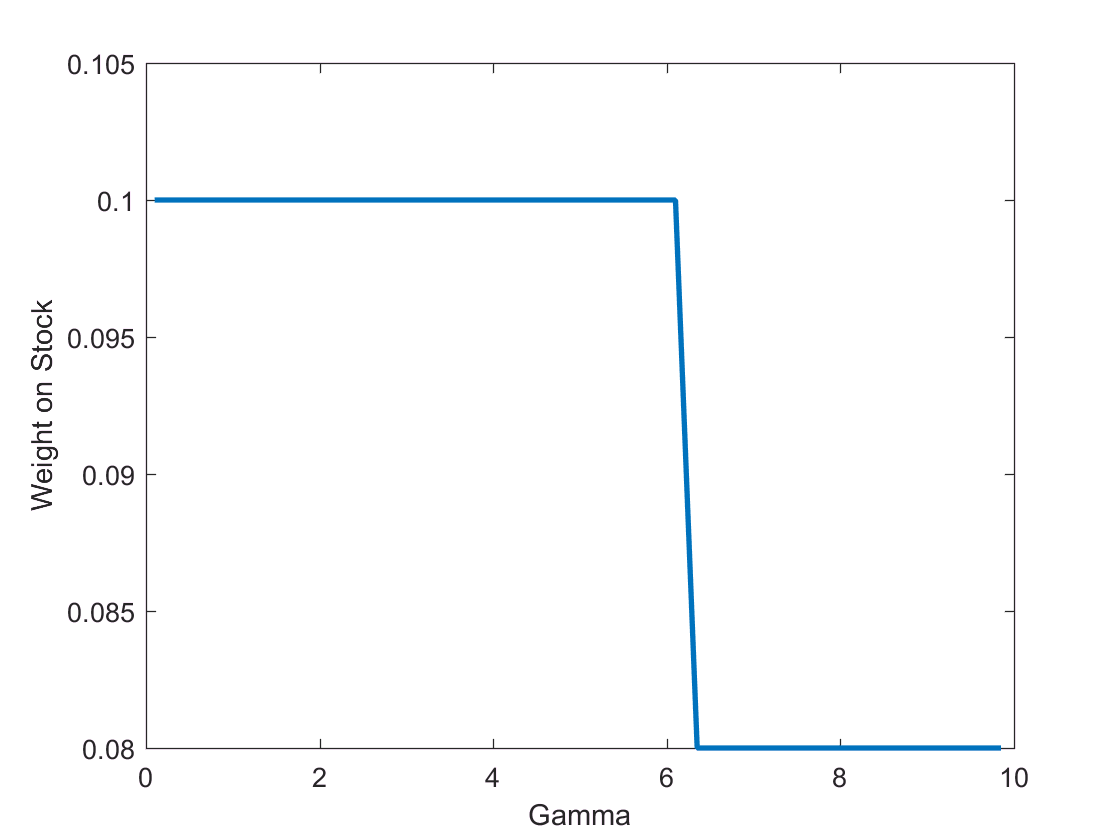

nu = 8;
e = trnd(nu,100000,1);
v = nu/(nu-2);
e = e/sqrt(v);
e = 0.08 + 0.2*e;
weights = 0:.02:1;
gammas=1.5:.25:10;
W_0 = 1;

EU = zeros(length(weights),length(gammas));
for j = 1:length(gammas)
    gamma = gammas(j);
    for i = 1:length(weights)
        w = weights(i);
        r = w * e + (1-w) * .01;
        mu = w * 0.08 + (1-w) * 0.01;
        EW_1 = W_0 * (1 + mu);
        mu_prime = mean([ones(size(r)) zeros(size(r)) (r-mu).^2 (r-mu).^3 (r-mu).^4])';
        EU(i,j) = expected_utility(mu_prime,EW_1,gamma);
    end
end

[~,loc] = max(EU);
h=plot(gammas,weights(loc));
set(h,'LineWidth',2)
xlabel('Gamma')
ylabel('Weight on Stock')